# Creating Filters in Swan

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

USE GEOMETRICAL FUNCTIONS !!!

## Preliminars

In this tutorial we will deal with Filters, which are crucial tools to control the *gray* regions of density fields or avoid checkerboarding problems during simulations. Given any function defined on our domain, Filters basically build a Finite Element Function based in the input function and smoothing it. The output function is typically a P1Function or a FGaussDiscontinuousFunction.

Before starting bulding our own filters, let's begin with some preliminars. First, we need a mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain (Figure 1):

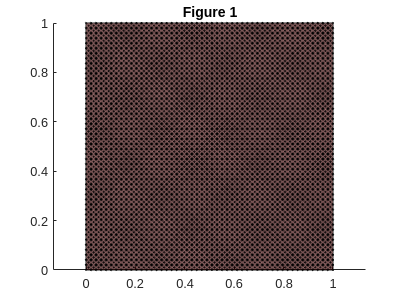

x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh = Mesh(m);

figure()
mesh.plot()
title('Figure 1')

Moreover, we need a *given *function. As a first example, we are going to create a Characteristic Function, which will be defined on previous [0,1]x[0,1] domain.

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1; % Number of dimensions of fHandle image. In this case is a scalar function.
s.mesh    = mesh;
fun       = AnalyticalFunction(s);


% delete..
AFunToP1 = fun.project('P1');
AFunToP1ToP1 = AFunToP1.project('P1');
norm(AFunToP1ToP1.fValues-AFunToP1.fValues)/norm(AFunToP1.fValues)

ans = 6.7095e-16

Let's also create the same function defined on an unfitted mesh:

x   = mesh.coord(:,1);
y   = mesh.coord(:,2);
phi = (x-0.5).^2+(y-0.5).^2-0.3.^2;

sLS.creatorSettings.value = phi;
sLS.initialCase           = 'given';
sLS.mesh                  = mesh;
levelSet                  = LevelSet(sLS);

sCF.uMesh = levelSet.getUnfittedMesh();
funLS        = CharacteristicFunction.create(sCF);

Previous functions return 0 everywhere except on a disc of height z=1, centered on (0.5,0.5) and radius 0.3. We can see how this characteristic function would look like by projecting it to a P0 FE function (Figure 2):

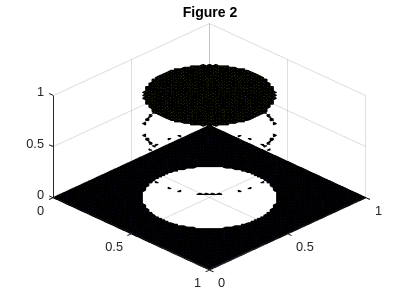

fP0 = fun.project('P0');
fP0.plot()
view(45,45)
title('Figure 2')

## Filters used for Density and gradients

### P1 Filter

Let's start now creating our first filter: P1. It works for functions that must be filtered on the original mesh, thus used for density problems or gradients, for instance. We will do so with the following lines

ss.designVarType = 'Continuous'; % Can also be 'Density'
ss.filterType    = 'P1';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.test          = P0Function.create(mesh,1);
ss.trial         = P1Function.create(mesh,1);
filter           = Filter.create(ss);

Note that previous quadType constant ('LINEAR') stands for the location of filter's gauss points when expressing the result as a FGaussDiscontinuousFunction. Now, we can obtain our first P1 function of our characteristic function by means of the following filter public command:

fP1 = filter.compute(fun,'QUADRATICMASS');

Arrays have incompatible sizes for this operation.

Error in FilterKernel/solveFilter (line 150)
            norm(xRk - xRk2)/norm(xRk) 

Error in FilterKernel/compute (line 28)
            obj.solveFilter();

<a href="matlab:helpview('matlab','error_sizeDimensionsMustMatch')" style="font-weight:bold"

fP02 = fP1.project('P0');
fP02.plot()
view(45,45)

fP11 = filter.compute(fP1,'QUADRATICMASS');
norm(fP1.fValues-fP11.fValues)

Note that we need to include another kind of quadrature, now the corresponding one to integrate the input function. The idea is to use an enough high order quadrature concerning the linearity of our input function. In this case, it will be enough to just use a linear order. Be careful then, we are dealing with two kind of quadratures: one concerning the gauss points where the filter result will be stored when asking for a FGaussDiscontinuousFunction, and another one concerning the number of gauss points used internally to integrate the input function.

We can plot the obtained P1 function (Figure 3) as:

fP1.plot()
view(45,45)
title('Figure 3')

Moreover, we can obtain the result expressed as a FGaussDiscontinuous function as:

%fG = filter.getFGaussFunction(fun,'LINEAR');
ss.designVarType = 'Continuous'; % Can also be 'Density'
ss.filterType    = 'P1';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.test          = P1Function.create(mesh,1);
ss.trial         = P0Function.create(mesh,1);
filter           = Filter.create(ss);
fP0 = filter.compute(fun,'QUADRATICMASS');
fP0.plot()
view(45,45)

fP01 = filter.compute(fP1,'QUADRATICMASS');
norm(fP0.fValues-fP01.fValues)




ss.designVarType = 'Continuous'; % Can also be 'Density'
ss.filterType    = 'P1';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.test          = P1Function.create(mesh,1);
ss.trial         = P1Function.create(mesh,1);
filter           = Filter.create(ss);
fP1 = filter.compute(fun,'QUADRATICMASS');
fP1.plot()
view(45,45)
fP03 = fP1.project('P0');
fP03.plot()
view(45,45)
x3 = fP03.fValues;

fP12 = filter.compute(fP1,'QUADRATICMASS');
norm(fP1.fValues-fP12.fValues)






ss.designVarType = 'Continuous'; % Can also be 'Density'
ss.filterType    = 'P1';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.test          = P0Function.create(mesh,1);
ss.trial         = P0Function.create(mesh,1);
filter           = Filter.create(ss);
fP0 = filter.compute(fun,'QUADRATICMASS');
fP02 = filter.compute(fP0,'QUADRATICMASS');
norm(fP0.fValues-fP02.fValues)

In this case, since the result is stored just in the gauss points location it does not make sense to plot the solution... although it is available as a public method (it consists in a standard projection to P1).

### PDE Filter

Let's create now a PDE filter, which also works for density problems or gradients. This new kind of filter works with additional parameters, being the most important one the LHStype. This parameter can be defined as:

- DiffReactNeumann - just filtering internal boundaries.

- DiffReactRobin - filtering internal and external boundaries.

- AnisotropicDiffReactNeumann - just filtering internal boundaries with a preferential direction.

- AnisotropicDiffReactRobin - filtering internal and external boundaries with a preferential direction.

Let's start by filtering isotropically just the internal boundaries with this filter:

ss.designVarType = 'Continuous';
ss.filterType    = 'PDE';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.scale         = 'MACRO'; % We can use MICRO for microstructural problems
ss.LHStype       = 'DiffReactNeumann'; % if not given, it is DiffReactNeumann by default
filter           = Filter.create(ss);

We can obtain and plot our P1 function (Figure 4) as:

fP1 = filter.compute(fun,'QUADRATICMASS');
fP1.plot()
view(45,45)
title('Figure 4')

Another important parameter that can be controlled is the 'epsilon', standing for the radius of influence. The higher the epsilon, the smoother the obtained solution (Figure 5) and, of course, the higher the amount of numerical information lost. Inherently, epsilon must be at least >=minimum mesh size.

epsilon = 4*mesh.computeMeanCellSize();
filter.updateEpsilon(epsilon);
fP1highEps = filter.getP1Function(fun,'LINEAR');
fP1highEps.plot()
view(45,45)
title('Figure 5')

Let's finish by filtering anisotropically the internal boundaries with this filter:

ss.designVarType = 'Continuous';
ss.filterType    = 'PDE';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.scale         = 'MACRO';
ss.LHStype       = 'AnisotropicDiffReactNeumann';
ss.CAnisotropic  = [100, 0; 0, 0.01];
ss.aniAlphaDeg   = 0;
filter           = Filter.create(ss);

Here it is necessary to define an expansion matrix CAnisotropic establishing the preferential direction and an aniAlphaDeg angle that rotates this behaviour. In this example, direction X is smoothed with a priority 10000 higher than the corresponding to direction Y. The obtained solution is the following (Figure 6):

fP1 = filter.getP1Function(fun,'LINEAR');
fP1.plot()
view(45,45)
title('Figure 6')

## Filters used for Level set

We could re-compute any example of previous section consdering unfitted mesh methods. We will use the funLS variable defined in the Preliminars as the input function.

### P1 Filter

Let's now create a P1Unfitted filter. It works for functions that must be filtered on the unfitted mesh, thus used for level set problems.

ss.designVarType = 'LevelSet';
ss.filterType    = 'P1';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
filter           = Filter.create(ss);

We can obtain our first FGauss function of our unfitted characteristic function by means of the following command:

%fP1 = filter.getP1Function(funLS,'LINEAR');
fG = filter.getFGaussFunction(funLS,'LINEAR');

### PDE Filter

Let's finally create a PDEUnfitted isotropic filter for just internal boundaries.

ss.designVarType = 'LevelSet';
ss.filterType    = 'PDE';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.scale         = 'MACRO'; % We can use MICRO for microstructural problems
ss.LHStype       = 'DiffReactNeumann'; % if not given, it is DiffReactNeumann by default
filter           = Filter.create(ss);

We can obtain and plot our last P1 function (Figure 7) as:

fP1 = filter.getP1Function(funLS,'LINEAR');
fP1.plot()
view(45,45)
title('Figure 7')

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!